% Frecuencia de muestreo
Fs = 1000;
% Periodo
T = 1/Fs;
% Longitud de la señal
L = 1000;
% Vector de tiempo multiplicado por el periodo
t = (-50:L-1)*T;

% Señales
x1 = cos(2*pi*50*t);
x2 = cos(2*pi*300*t);
x3 = cos(2*pi*150*t);
x4 = exp(-2*abs(t));

X = [x1; x2; x3; x4];

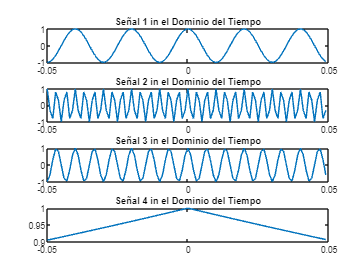

for i = 1:4
    subplot(4,1,i)
    plot(t(1:100),X(i,1:100))
    title("Señal " + num2str(i) + " in el Dominio del Tiempo")
end

dim = 2;
Y = fft(X,L,dim);

% Espectro de un lado y dos lados de la señal
P2 = abs(Y/L);
P1 = P2(:,1:L/2+1);
P1(:,2:end-1) = 2*P1(:,2:end-1);

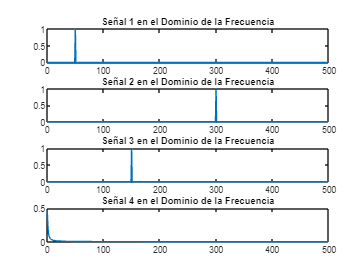

for i=1:4
    subplot(4,1,i)
    plot(0:(Fs/L):(Fs/2-Fs/L),P1(i,1:L/2))
    title("Señal " + num2str(i) + " en el Dominio de la Frecuencia")
end